# Setup and Variable Parameters

clc
clear
warning('off','all')

%Plant
Cu = 3.53e3;
Cw = 7.47e2;
I = 1.97e3;
G_plant = tf(Cu,[I Cw 0])

G_plant =
 
        3530
  ----------------
  1970 s^2 + 747 s
 
Continuous-time transfer function.




%V_set = .1*ones(1,size(t,2)); %step
%unitstep = t>=0;

# Chirp Input

%Input
N_temp = 10;
delta_t = 0.001;
t = 0:delta_t:N_temp;
rampmag = 0.03;
V_set = 0.05*chirp(t,0.1,t(end),2,'linear',-90);
V_in = [t' V_set'];

%Model Setup
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridSaccadeFF';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Parameters
sac_time = 0.3; %Saccade completion "delay"
n_delay = 0.1; %Neurological Delay
T_lim_up = 3e-2; %Biological Torque Limit upper
T_lim_low = -3e-2; %Biological Torque Limit upper
switch_thresh = .005; %Integrated error threshold for switching between smooth/saccadic
sac_thresh = .1; %Position error threshold for finishing saccade
K_P = 10; %Proportional Gain
K_I = 1; %Integral Gain of smooth system

out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');

fprintf('Input : %gt',rampmag)

Input : 0.03t

fprintf('Neurological Delay: %g',n_delay)

Neurological Delay: 0.1

fprintf('Saccade Completion "Delay:" %g',sac_time)

Saccade Completion "Delay:" 0.3

fprintf('Integrated Error Switching Threshold: %g',switch_thresh)

Integrated Error Switching Threshold: 0.005

fprintf('Smooth System Proportional Gain: %g',K_P)

Smooth System Proportional Gain: 10

fprintf('Smooth System Integral Gain: %g',K_I)

Smooth System Integral Gain: 1

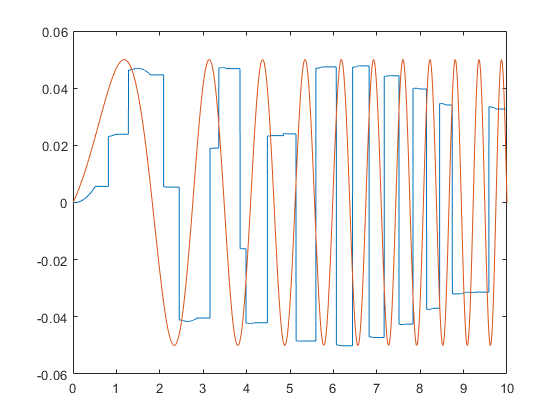


figure
plot(out.tout,out.V_out,t,V_set)

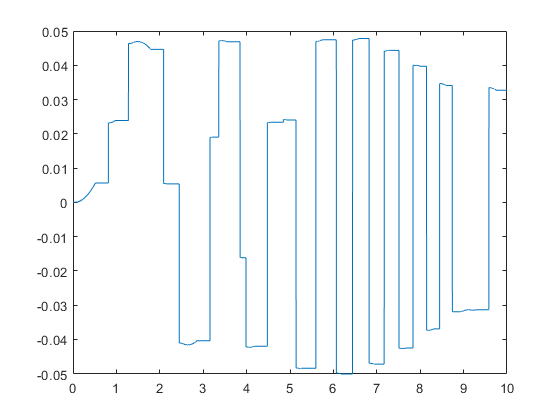

figure
plot(out.tout,out.V_out)

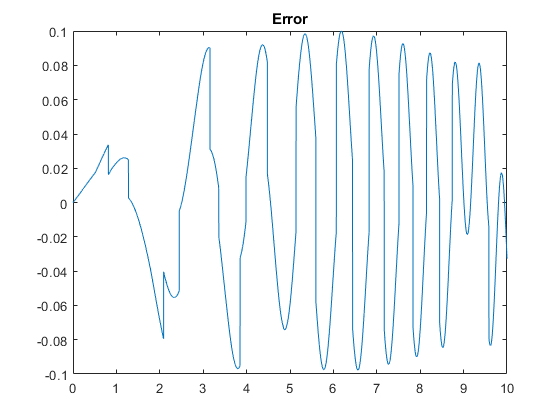

figure
plot(out.tout,V_set'-out.V_out)
title("Error")

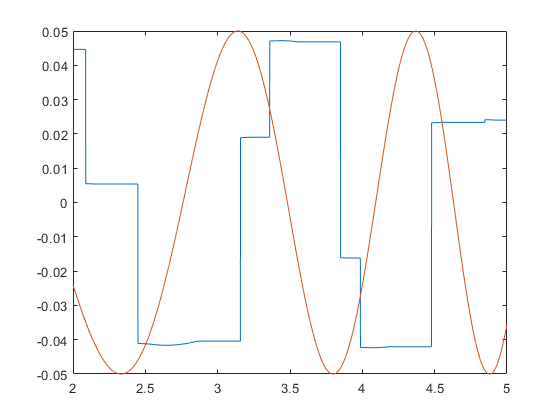

figure
plot(out.tout,out.V_out,t,V_set)
xlim([2 5])